# SC-HW5-312657008-江祐姍

## 採用Matlab進行運算

## Find the matrix inverse of the correlation matrix for AR(1) time series symbolically and numerically. $\Sigma_{n\times n} = (\rho^{\vert i-j \vert})$

## (1) Symbolic Computaion

for n = 2:5
    [A, invA] = calculateMatrix(n);
end

Matrix A:


$$\left(\begin{array}{cc} 1 & \rho \\ \rho & 1 \end{array}\right)$$

Inverse of A:


$$\left(\begin{array}{cc} -\frac{1}{\rho^{2}-1} & \frac{\rho }{\rho^{2}-1}\\ \frac{\rho }{\rho^{2}-1} & -\frac{1}{\rho^{2}-1} \end{array}\right)$$

Matrix A:


$$\left(\begin{array}{ccc} 1 & \rho & \rho^{2}\\ \rho & 1 & \rho \\ \rho^{2} & \rho & 1 \end{array}\right)$$

Inverse of A:


$$\left(\begin{array}{ccc} -\frac{1}{\rho^{2}-1} & \frac{\rho }{\rho^{2}-1} & 0\\ \frac{\rho }{\rho^{2}-1} & -\frac{\rho^{2}+1}{\rho^{2}-1} & \frac{\rho }{\rho^{2}-1}\\ 0 & \frac{\rho }{\rho^{2}-1} & -\frac{1}{\rho^{2}-1} \end{array}\right)$$

Matrix A:


$$\left(\begin{array}{cccc} 1 & \rho & \rho^{2} & \rho^{3}\\ \rho & 1 & \rho & \rho^{2}\\ \rho^{2} & \rho & 1 & \rho \\ \rho^{3} & \rho^{2} & \rho & 1 \end{array}\right)$$

Inverse of A:


$$\begin{array}{l} \left(\begin{array}{cccc} -\frac{1}{\rho^{2}-1} & \sigma_{1} & 0 & 0\\ \sigma_{1} & -\frac{\rho^{2}+1}{\rho^{2}-1} & \sigma_{1} & 0\\ 0 & \sigma_{1} & -\frac{\rho^{2}+1}{\rho^{2}-1} & \sigma_{1}\\ 0 & 0 & \sigma_{1} & -\frac{1}{\rho^{2}-1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\rho }{\rho^{2}-1} \end{array}$$

Matrix A:


$$\left(\begin{array}{ccccc} 1 & \rho & \rho^{2} & \rho^{3} & \rho^{4}\\ \rho & 1 & \rho & \rho^{2} & \rho^{3}\\ \rho^{2} & \rho & 1 & \rho & \rho^{2}\\ \rho^{3} & \rho^{2} & \rho & 1 & \rho \\ \rho^{4} & \rho^{3} & \rho^{2} & \rho & 1 \end{array}\right)$$

Inverse of A:


$$\begin{array}{l} \left(\begin{array}{ccccc} -\frac{1}{\rho^{2}-1} & \sigma_{1} & 0 & 0 & 0\\ \sigma_{1} & -\frac{\rho^{2}+1}{\rho^{2}-1} & \sigma_{1} & 0 & 0\\ 0 & \sigma_{1} & -\frac{\rho^{2}+1}{\rho^{2}-1} & \sigma_{1} & 0\\ 0 & 0 & \sigma_{1} & -\frac{\rho^{2}+1}{\rho^{2}-1} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & -\frac{1}{\rho^{2}-1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\rho }{\rho^{2}-1} \end{array}$$

上方展示了 n = 2 到 n = 5  的 AR(1) 矩陣及其反矩陣。

由上方結果可以看出一些規律，當$\rho \not= \pm 1$時，可得到反矩陣之一般式如下：


$$\ast \ when \  n =2\\
\begin{cases} \\
if \ i=j=1 \ or \ n, \ \Sigma^{-1}_{ij}= -\frac{1}{\rho^2-1} \ \\
if \ \vert i-j \vert =1, \ \Sigma^{-1}_{ij} =  \frac{\rho}{\rho^2-1} \\
\end{cases} \\


\ast \ when \  n \ge 3\\
\begin{cases} \\
if \ i=j=1 \ or \ n, \ \Sigma^{-1}_{ij}= -\frac{1}{\rho^2-1} \ \\
if \ i=j= 2, ..., n-1 , \ \Sigma^{-1}_{ij}= -\frac{\rho^2+1}{\rho^2-1} \\
if \ \vert i-j \vert =1, \ \Sigma^{-1}_{ij} =  \frac{\rho}{\rho^2-1} \\
otherwise,\ \Sigma^{-1}_{ij}  = 0
\end{cases} \\
$$


以數學歸納法證明上方觀察到的規律：

goal : $\textrm{When}\;\textrm{the}\;\textrm{matrix}\;\textrm{is}\;\sum_{n\times n} =\rho^{\left|i-j\right|} ,\;\textrm{then}$$\Sigma^{-1}_{n \times n} =$

          
$$\left\lbrack \begin{array}{ccccc}
\frac{-1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & 0 & \cdots  & 0\\
\frac{\rho }{\rho^2 -1} & -\frac{\rho^2 +1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & \vdots \\
0 & \frac{\rho }{\rho^2 -1} & \ddots  & \frac{\rho }{\rho^2 -1} & 0\\
\vdots  & 0 & \frac{\rho }{\rho^2 -1} & -\frac{\rho^2 +1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1}\\
0 & \cdots  & 0 & \frac{\rho }{\rho^2 -1} & \frac{-1}{\rho^2 -1}
\end{array}\right\rbrack$$


(i) 當 n = 3 時,

    $\Sigma_{3 \times 3}$ = $\left\lbrack \begin{array}{ccc}
1 & \rho^2  & \rho^3 \\
\rho^2  & 1 & \rho^2 \\
\rho^3  & \rho^2  & 1
\end{array}\right\rbrack$


$$det(\Sigma_{3 \times 3}) =1+ \rho^4 +\rho^4 - \rho^4 -\rho^2-\rho^2 = 1-2\rho^2 +\rho^4 =(\rho^2 -1)(\rho^2 - 1)$$



$$\Sigma_{3 \times 3}^{-1} =$$

$$\frac{1}{\left(\rho^2 -1\right)\left(\rho^2 -1\right)}$$

$$\left\lbrack \begin{array}{ccc}
1-\rho^2  & -\left(\rho -\rho^3 \right) & 0\\
-\left(\rho -\rho^3 \right) & \left(1-\rho^4 \right) & -\left(\rho -\rho^3 \right)\\
0 & -\left(\rho -\rho^3 \right) & 1-\rho^2 
\end{array}\right\rbrack$$


         
$$=$$

$$\left(\begin{array}{ccc}
-\frac{1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & 0\\
\frac{\rho }{\rho^2 -1} & -\frac{\rho^2 +1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1}\\
0 & \frac{\rho }{\rho^2 -1} & -\frac{1}{\rho^2 -1}
\end{array}\right)$$


所以成立。

(ii) 設   n = k 時成立，也就是說，$\;\sum_{k\times k} =\rho^{\left|i-j\right|} ,\;\textrm{then}\;\sum_{k\times k}^{-1} =$$\left\lbrack \begin{array}{ccccc}
\frac{-1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & 0 & \cdots  & 0\\
\frac{\rho }{\rho^2 -1} & -\frac{\rho^2 +1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & \vdots \\
0 & \frac{\rho }{\rho^2 -1} & \ddots  & \frac{\rho }{\rho^2 -1} & 0\\
\vdots  & 0 & \frac{\rho }{\rho^2 -1} & -\frac{\rho^2 +1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1}\\
0 & \cdots  & 0 & \frac{\rho }{\rho^2 -1} & \frac{-1}{\rho^2 -1}
\end{array}\right\rbrack$

     則 當 n = k+1時$,\sum_{\left(k+1\right)\times \left(k+1\right)} \;\;=\left\lbrack \begin{array}{cc}
\sum_{k\times k}  & v\\
v^T  & 1
\end{array}\right\rbrack ,\;v=\left\lbrack \begin{array}{c}
\rho^{k+1} \\
\vdots \\
\rho 
\end{array}\right\rbrack$

  
$$Note. \\
若有一矩陣可寫成下方形式：\
$$



$$
$\left(\begin{array}{cc}
A & B\\
C & D
\end{array}\right)$ 

其中 A 和 D 是方陣，則反矩陣$\left(\begin{array}{cc}
A & B \\
C & D 
\end{array}\right) ^{-1}$
可以表示為：$$



$$$\left(\begin{array}{cc}
(A - BD^{-1}C)^{-1} & -A^{-1}B(D - CA^{-1}B)^{-1} \\
-D^{-1}C(A - BD^{-1}C)^{-1} & (D - CA^{-1}B)^{-1}
\end{array}\right)$ $$


運用上方的note


$$\sum_{\left(k+1\right)\times \left(k+1\right)}^{-1} \;\;=\left\lbrack \begin{array}{cc}
{\left(\sum_{k\times k} -vv^T \right)}^{-1}  & -\sum_{k\times k}^{-1} v{\left(I-\;v^T \sum_{k\times k}^{-1} v\right)}^{-1} \\
-{\left(I-\;v^T \sum_{k\times k}^{-1} v\right)}^{-1} v^T \sum_{k\times k}^{-1}  & {\left(I-\;v^T \sum_{k\times k}^{-1} v\right)}^{-1} 
\end{array}\right\rbrack \;\;\;\;\;\;$$



$$\begin{array}{l}
\ast \;\textrm{計算}\;\sum_{k\times k} -vv^{T\;\;} \\
{\left(\sum_{k\times k} -vv^{T\;\;} \right)}_{\textrm{ij}} =\left(\sum_{k\times k} \;\right){\;}_{\textrm{ij}} -v_i \;v_{j\;} =\rho^{|i-j|} -\rho {\;}^{i+j} 
\end{array}$$



$$\ast \;\textrm{計算}\left(I-\;v^T \sum_{k\times k}^{-1} v\right)$$



$$v^T \sum_{k\times k}^{-1} v\;=\;\sum_{i\;=1}^k v_i {\left(\Sigma_{k\times k} \right)}^{-1} v_i \;=\sum_{i\;=1}^k \rho^i {\left(\Sigma_{k\times k} \right)}^{-1} \rho^i \;$$
   


$$\begin{array}{l}
{\left(I-\;v^T \sum_{k\times k}^{-1} v\right)}_{\textrm{ij}} =1-\sum_{i\;=1}^k \rho^i {\left(\Sigma_{k\times k} \right)}^{-1} \rho^{i\;} \;,\;i=j\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\sum_{i\;=1}^k \rho^i {\left(\Sigma_{k\times k} \right)}^{-1} \rho^i \;\;,\;\;i\not= j
\end{array}$$


再帶回上面, 得到$\;\sum_{\left(k+1\right)\times \left(k+1\right)}^{-1} =$$\left\lbrack \begin{array}{ccccc}
\frac{-1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & 0 & \cdots  & 0\\
\frac{\rho }{\rho^2 -1} & -\frac{\rho^2 +1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & \frac{\rho }{\rho^2 -1} & \vdots \\
0 & \frac{\rho }{\rho^2 -1} & \ddots  & \frac{\rho }{\rho^2 -1} & 0\\
\vdots  & 0 & \frac{\rho }{\rho^2 -1} & -\frac{\rho^2 +1}{\rho^2 -1} & \frac{\rho }{\rho^2 -1}\\
0 & \cdots  & 0 & \frac{\rho }{\rho^2 -1} & \frac{-1}{\rho^2 -1}
\end{array}\right\rbrack$ 所以成立。

(iii) By (i), (ii), 及 M.I.， 可得


$$
when \  n \ge 3\\
\begin{cases} \\
if \ i=j=1 \ or \ n, \ \Sigma^{-1}_{ij}= -\frac{1}{\rho^2-1} \ \\
if \ i=j= 2, ..., n-1 , \ \Sigma^{-1}_{ij}= -\frac{\rho^2+1}{\rho^2-1} \\
if \ \vert i-j \vert =1, \ \Sigma^{-1}_{ij} =  \frac{\rho}{\rho^2-1} \\
otherwise,\ \Sigma^{-1}_{ij}  = 0
\end{cases} \\$$


## (2)  $When \ \rho = 1 - 10^{-d}$ $,\ where\ d = 1, 2, 3, ...$  $Solve \ \Sigma^{-1}\ numerically.$

### 利用內建函數inv計算反方陣

for n = 2:7
    [A, invA, d] = calculateMatrixnumerically(n);
end

* 當 n = 2, d = 14 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
 
* 當 n = 3, d = 14 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
 
* 當 n = 4, d = 14 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
 
* 當 n = 5, d = 15 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
 
* 當 n = 6, d = 15 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
 
* 當 n = 7, d = 15 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
 


上方展示了，隨著 d 改變，從能計算出反方陣到無法算出反方陣的結果(此處無法算出為Inf)，由於程式會自行四捨五入，因此會放大誤差，造成無法計算出。

可以發現到當n = 2，d = 14, rho = 1 - 10^(-14) 時無法計算出反方陣。

並觀察 n 從 3 到 20 在 d 值為何時會無法藉由程式計算出，發現到與 n = 2 情形相似，也就是說，當 d 值為 14 左右無法計算出正確的反方陣。 

接著，不使用套件，做出LU、Cholesky、QR、SVD分解後的反方陣。(若是將其結果都輸出會導致篇幅過大，因此只輸出到哪時候無法計算，此外，加速計算速度最多只計算到5*5的方陣)

### LU 分解

for n = 2:5
    [A, invA, d] = LU(n);
end

* 當 n = 2, d = 14 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
* 當 n = 3, d = 14 時
無法進行 LU 分解，矩陣可能不可逆或存在數值問題
* 當 n = 4, d = 14 時
無法進行 LU 分解，矩陣可能不可逆或存在數值問題
* 當 n = 5, d = 14 時
無法進行 LU 分解，矩陣可能不可逆或存在數值問題


小結：無論n值為何，當 d = 14時，無法進行 LU 分解，矩陣可能不可逆或存在數值問題

### Cholesky 分解

for n = 2:5
    [A, invA, d] = CF_inv(n);
end

L cannot not be found out


* 當 n = 2, d = 14 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
L cannot not be found out


* 當 n = 3, d = 14 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
L cannot not be found out


* 當 n = 4, d = 14 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
* 當 n = 5, d = 1 時
無法進行 cholesky 分解，矩陣可能不可逆或存在數值問題


小結：Cholesky 分解 ，隨著d值變大，會無法計算或者是反方陣不存在。

### QR 分解

#### QR by means of Gram-Schmidt

for n = 2:5
    [A, invA, d] = QR_GS(n);
end

* 當 n = 2, d = 14 時
無法進行 QR by means of Gram-Schmidt分解，矩陣可能不可逆或存在數值問題
* 當 n = 3, d = 14 時
無法進行 QR by means of Gram-Schmidt分解，矩陣可能不可逆或存在數值問題


* 當 n = 4, d = 14 時
無法利用程式計算反矩陣(反方陣中元素會出現Inf)
* 當 n = 5, d = 15 時
無法進行 QR by means of Gram-Schmidt分解，矩陣可能不可逆或存在數值問題


#### QR by means of  Householder reflections

for n = 2:5
    [A, invA, d] = QR_HR_inv(n);
end

* 當 n = 2,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 3,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 4,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 5,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 


####  QR by means of Givens  rotations 

for n = 2:5
    [A, invA, d] = QR_GR_inv(n);
end

* 當 n = 2,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 3,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 4,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 5,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 


小結：QR 分解（Gram-Schmidt）在d = 15就無法進行分解，但是其他兩種分解方式Householder reflections以及 Givens rotations 就不具此問題，當rho值很小的時候依然可以做分解，並計算反矩陣。

### SVD分解

for n = 2:5
    [A, invA, d] = SVD_inv(n);
end

* 當 n = 2,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 3,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 4,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 
* 當 n = 5,且rho很小(1 - 10^(-100))時, 依然可以利用此方法求得反方陣
 


小結：SVD分解在當rho值很小的時候依然可以做分解，並計算反矩陣。

### 各種方法之反矩陣誤差比較

由上可知，當 d = 10時，幾乎都能計算出反矩陣(有些無法計算超過 d = 10 的反矩陣，矩陣的特徵值可能變得非常接近零，進而導致數值穩定性問題和計算精度問題)。因此，選擇從 d = 1 到 13 比較不同方法計算反矩陣的誤差。

比較方法為 $norm(I - A * invA)$

當矩陣大小為 2x2


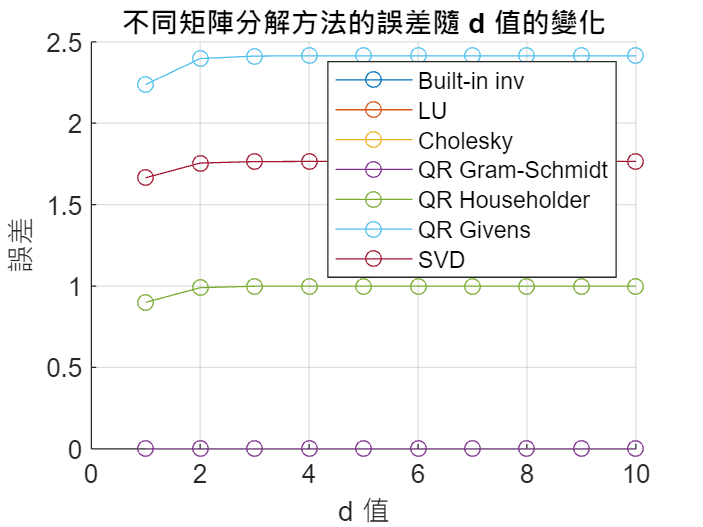

當矩陣大小為 3x3


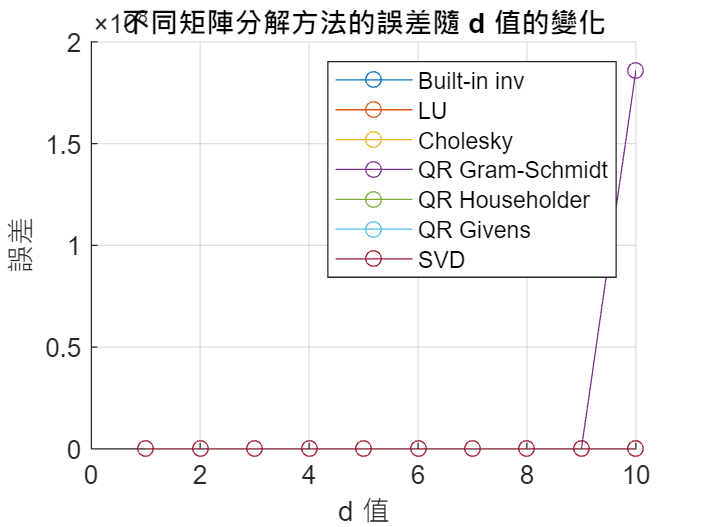

當矩陣大小為 4x4


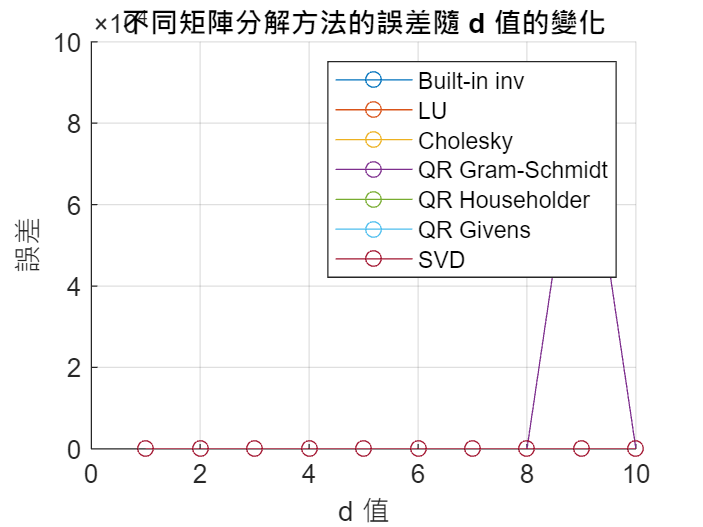

當矩陣大小為 5x5


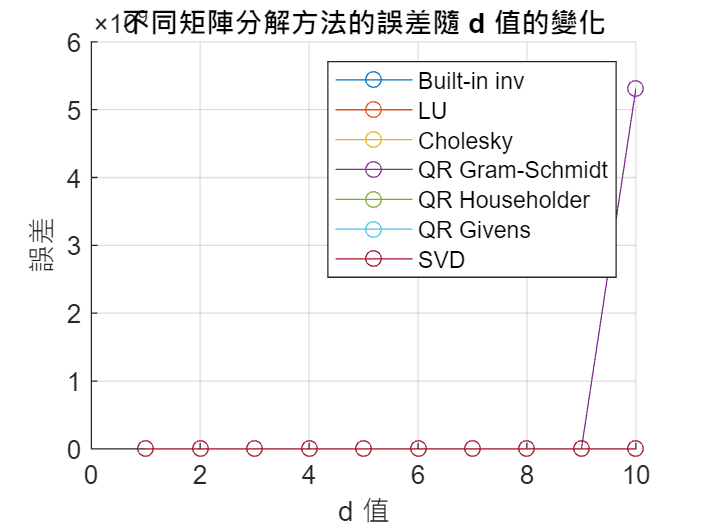

for n = 2:5
    fprintf(['當矩陣大小為 ' num2str(n) 'x' num2str(n) '\n']);
    plotErrorVariationWithD(n);
end

由誤差圖可看出隨著矩陣大小 *n* 的增加，誤差會變小，可能的原因如下：

- 數值穩定性增加：大多數數值計算方法在處理較大的矩陣時更穩定，因為它們通常涉及更多的數值操作。

- 數值影響減小：隨著矩陣大小增加，個別數值對整個計算的影響通常會減小。因此，任何數值上的微小誤差對整個計算的影響也會相應減小。

當 n = 2 時，可以考慮利用內建函數inv、LU、Cholesky、QR Gram-Schmidt求反矩陣，會有較小的誤差。

當 n >= 3 時， 可以考慮除了QR Gram-Schmidt外的方法求反矩陣，會有較小的誤差。